# DATA 7: Resting-state fMRI Brain Network

% Data was published in 
%
% @article{huang.2020.NM,
%   title={Statistical model for dynamically-changing correlation matrices with application to  brain connectivity},
%   author={Huang, S.-G. and Samdin, S.-T. and Ting, C.M. and Ombao, H. and Chung, M.K.},
%   journal={Journal of Neuroscience Methods},
%   volume={331},
%   pages={108480},
%   year={2020}
% }
% arXiv version https://arxiv.org/pdf/1812.10050
%
% If you are using data/codes, cite this paper. This is NOT public domain
% data. Do not distribute/upload data to other sites. 
%
% (C) 2025 Moo K. Chung
% University of Wisconsin-Madison
% Last update: 2026 Feb 10


## Directed edge flow matrix

% To construct the time-varying asymmetric connectivity matrix (Y_tau_all),
% we analyze rs-fMRI data across 121 temporal windows, sampled every 5 TRs
% (approximately 3.6 s) from TR 300 to TR 900. The first 299 and the last
% 200 TRs of the original time series are discarded to allow for T1
% equilibration effects, to ensure the participant has reached a stable
% resting state, and to provide a sufficient buffer for the 40 s window
% length and the 20 s temporal lag.
%
% Each window uses a 56-frame duration (approximately 40 s) together with a
% fixed 28-frame temporal lag (approximately 20 s) to characterize
% predictive interactions among 116 brain regions. For each window, we
% compute lagged Pearson correlations between all region pairs by correlating
% the current activity of region i with the delayed activity of region j.
% To assign a unique dominant interaction for each unordered pair, we enforce
% antisymmetry: the direction with the larger correlation magnitude is
% retained as a positive flow (i -> j), while the reverse direction is
% assigned its negative. We then apply a sparsity threshold (tau = 0.6) so
% that only dominant interactions exceeding this threshold are preserved.
% The resulting antisymmetric matrix encodes the robust directed functional
% architecture of the brain as it evolves over time. To save space, we only
% stored upper trinagle entries of dominant correlation values for 50
% subjects.

load rsfMRIedgeflows;
n_nodes = 116;
Ytau_all = flows2matrix(Flows, n_nodes);

## Displyaing underlying brain surface

sparse_stat(Ytau_all) %will show there are about 10% of directed edges (aveaged over time and subjects)

Sparsity: 89.95% zeros (73229206 / 81408800 entries)


% Display AAL116 surface, nodes, and anatomical labels
% It displays (i) the cortical surface patch as a neutral background,
% (ii) ROI node locations on the surface, and (iii) anatomical ROI labels
% positioned near each node with mild depth-adaptive scaling. 
%
% Depth-adaptive visualization follows the approach illustrated in Figure 6 of
% @article{huang.2020.NM,
%   title   = {Statistical model for dynamically-changing correlation matrices with application to brain connectivity},
%   author  = {Huang, S.-G. and Samdin, S.-T. and Ting, C.-M. and Ombao, H. and Chung, M. K.},
%   journal = {Journal of Neuroscience Methods},
%   volume  = {331},
%   pages   = {108480},
%   year    = {2020}
% }
%
% If you use this visualization, please cite the above paper.

AAL = AAL_display_surface;

## Displaying underling flow

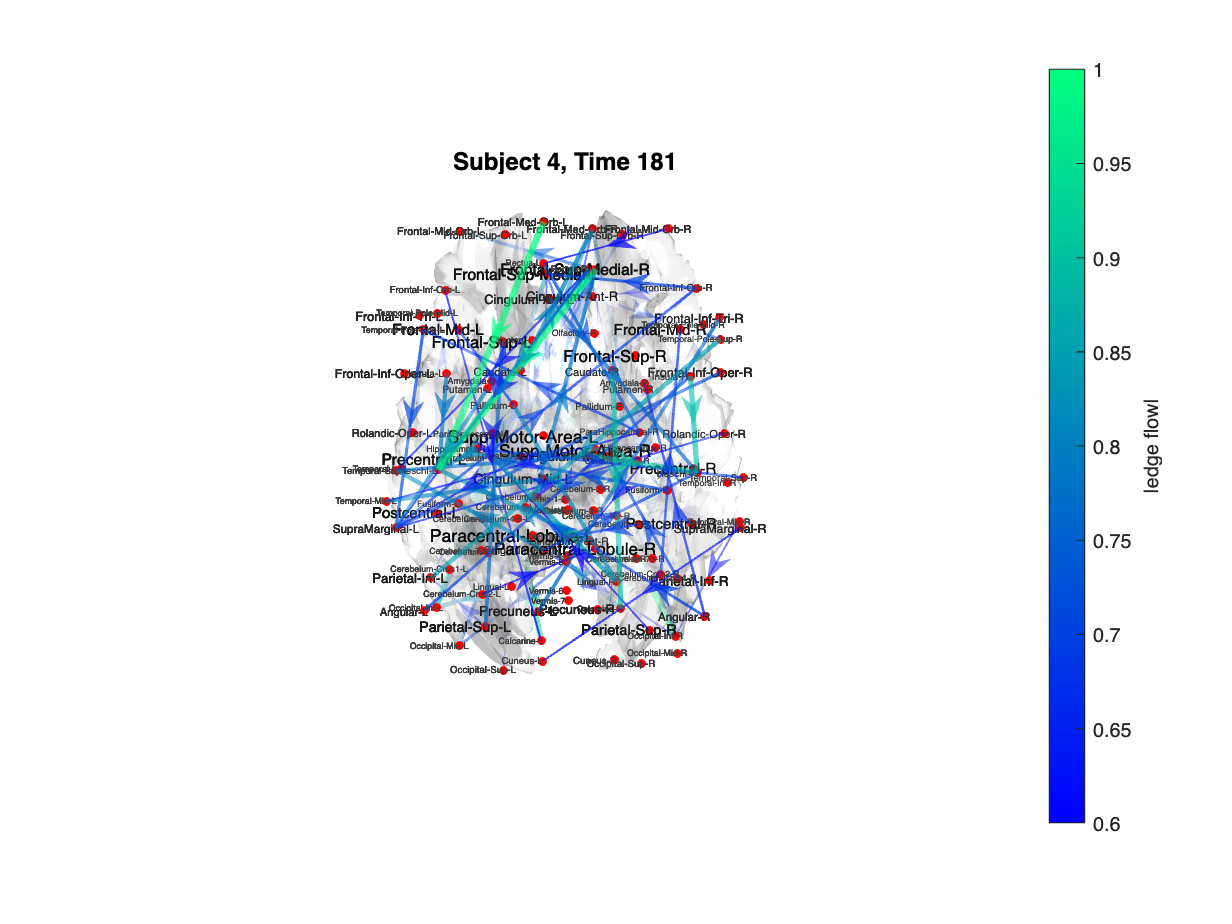

% Convert directed connectivity tensor into edge-flow representation
% Flows : [E x nT x nSub] edge flows on the AAL116 1-skeleton (i<j base edges)
% Edges : [E x 2]        lexicographic base edge list (i<j)

AAL = AAL_display_surface;                 % draw AAL surface, nodes, and labels
[Flows, Edges] = adj2flows(Ytau_all);      % convert adjacency matrices to edge flows
Vertices = AAL.vertices;                  % ROI coordinates (display-ready)

% Select ONE subject and ONE time point
tIdx = 100;                                % time window index
sIdx = 4;                                  % subject index
% Display only the strongest directed interactions
q = 50;                                   % number of edges with largest |flow|
% Extract edge-flow vector for the selected (time, subject)
edgeflows = Flows(:, tIdx, sIdx);          % [E x 1] signed edge flows

% Overlay directed edge flows on the anatomical template
flow2display(edgeflows, Edges, Vertices, q); 
rotate3d on; % if you want to rotate images

## Scientific Animation

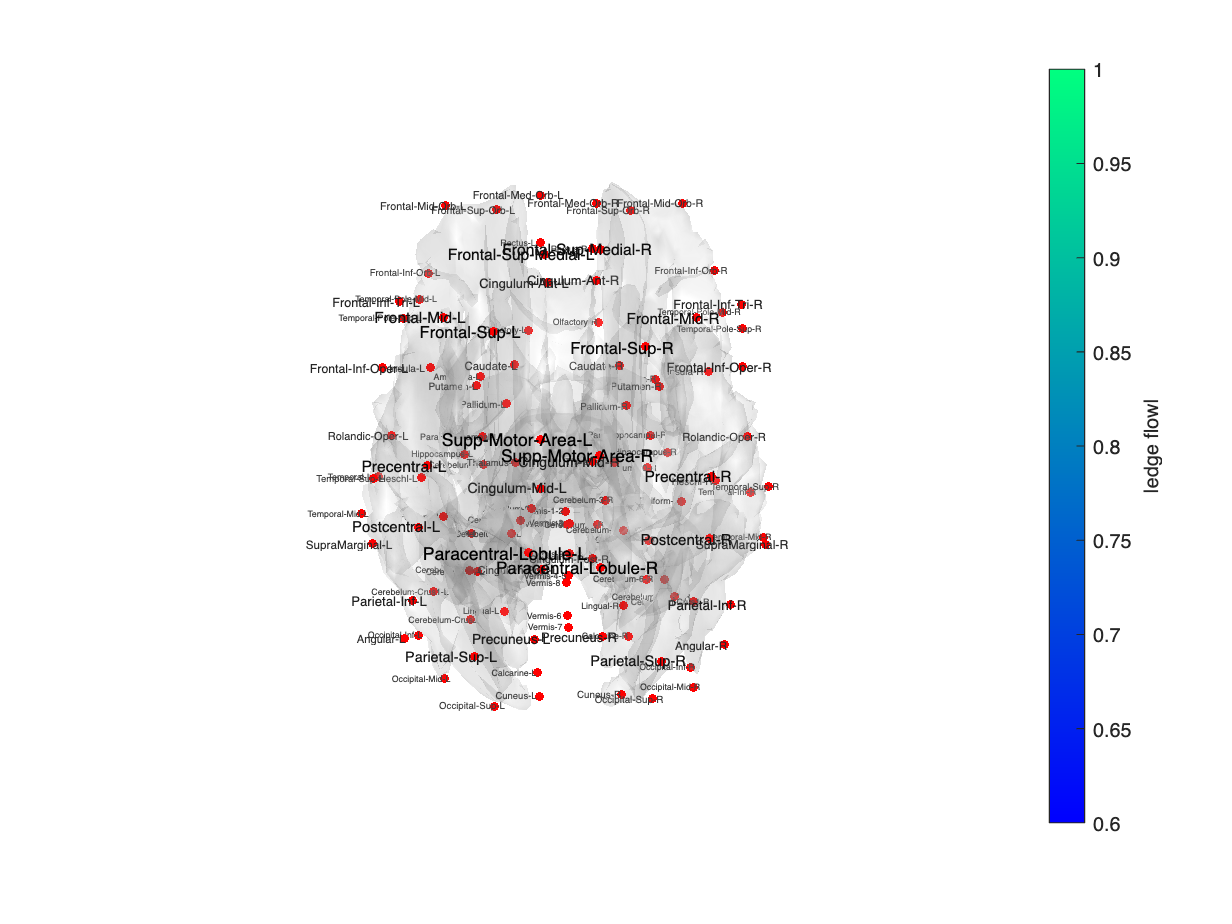

% Dynamic display of edge flows over time for ONE subject (AAL116)
AAL = AAL_display_surface;                  
[Flows, Edges] = adj2flows(Ytau_all);       % [E x nT x nSub]
Vertices = AAL.vertices;

sIdx = 4;                                   % subject index
q    = 50;                                  % show top-q edges by |flow|
nT   = size(Flows,2);

cb = colorbar;                             % create colorbar ONCE
caxis([0.6 1]);                        % global fixed scale
colormap(winter);                          % cold map, fixed
ylabel(cb,'|edge flow|');

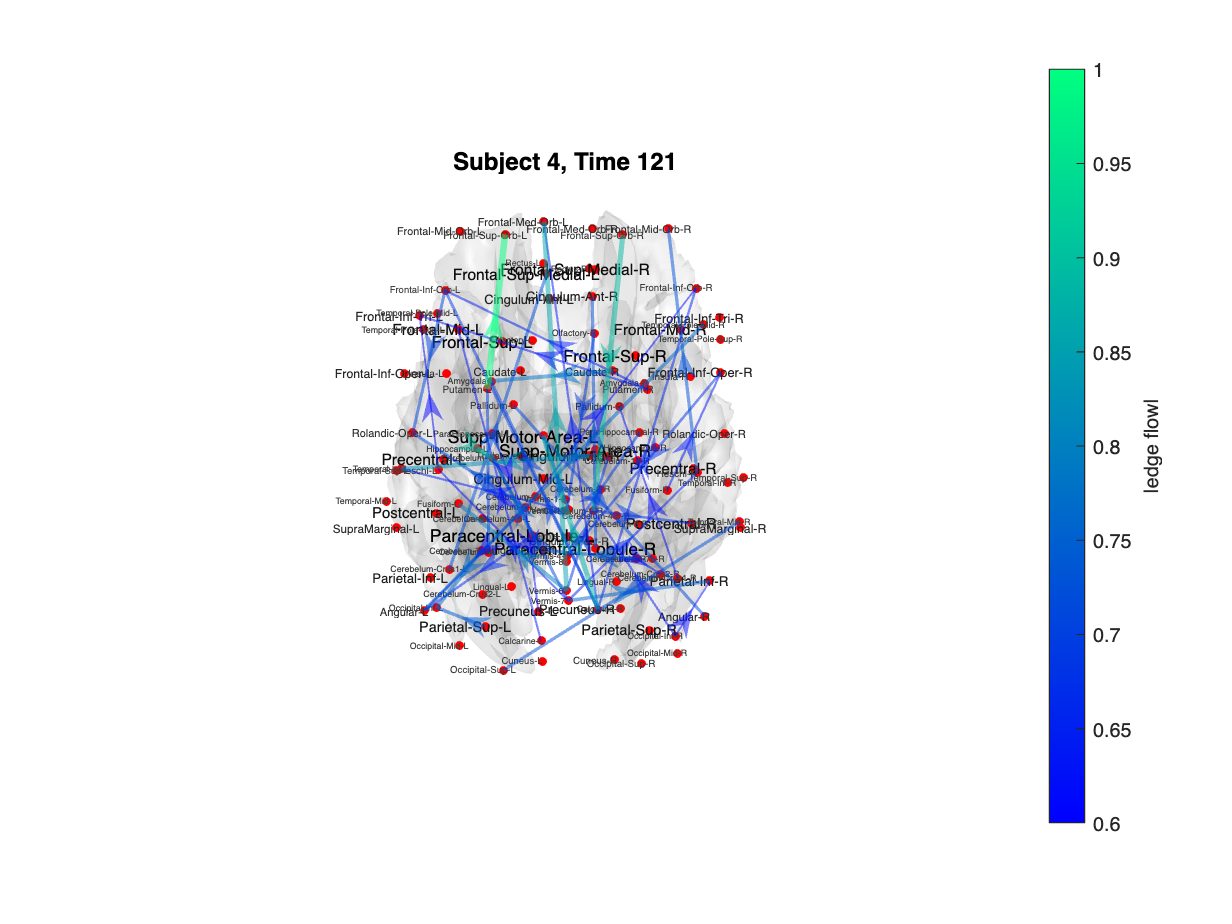



for tIdx = 1:nT
    cla;                                    % clear axes (keep same figure)
    AAL_display_surface;                    % redraw anatomical scaffold
    edgeflows = Flows(:,tIdx,sIdx);         % [E x 1] edge flows at time tIdx
    
    flow2display(edgeflows, Edges, Vertices, q);   % overlay flows
    
    caxis([0.6 1]);                  
    title(sprintf('Subject %d, Time %d', sIdx, tIdx));
    drawnow;
    pause(0.02);                            % adjust speed
end

## PROJECT 12: Dynamic Directed Network Analysis and Visualization

% Goal: The goal of this project is to introduce students to the
% analysis of dynamic, time-varying network data. Students will learn how
% to model and analyze time-varying directed graphs and networks, represented
% as edge flows. Emphasis is modeling and analyzing directed network
% structure, and on understanding how temporal evolution reveals organizational
% patterns over time and subjects. This framework is broadly applicable to many 
% forms of multivariate time-series data, including but not limited to brain networks, 
% biological interaction networks, and other dynamical systems.
%
% Description: Students analyze dynamic directed networks represented as a
% sequence of time-indexed adjacency matrices, which are reformulated as
% time-evolving edge flows on a fixed node set. Students investigate these
% networks using geometric and topological methods for directed flows that
% are covered in class, and systematically compare their performance with
% classical graph theory features that are largely developed for static,
% undirected graphs. 
% 
% A core component of the project is the development of effective
% visualization strategies for dynamic directed networks, including static
% summaries and time-resolved animations that reveal how edge-flow patterns
% are persisent and evolve over time. Students are expected to develop 
% statistically principled approaches for averaging edge-flow patterns over 
% time and across samples, and to design and implement statistical inference 
% procedures tailored to directed edge flows.
% 
% Learning Outcomes: Students will gain hands-on experience with dynamic, 
% time-varying directed network representations. Students will develop both conceptual 
% and practical understanding of how directed interactions differ from classical 
% undirected network models and why standard graph-theoretic features may fail 
% to capture asymmetric, evolving structure. Students will acquire skills in applying 
% geometric and topological methods studied in class to directed flows, 
% and constructing statistically principled inference procedures for dynamic networks. 
%
% Upon completion, students will be able to critically analyze and interpret 
% directed network dynamics across time and subjects, and extend these methodologies 
% to a wide range of multivariate time-series network data.